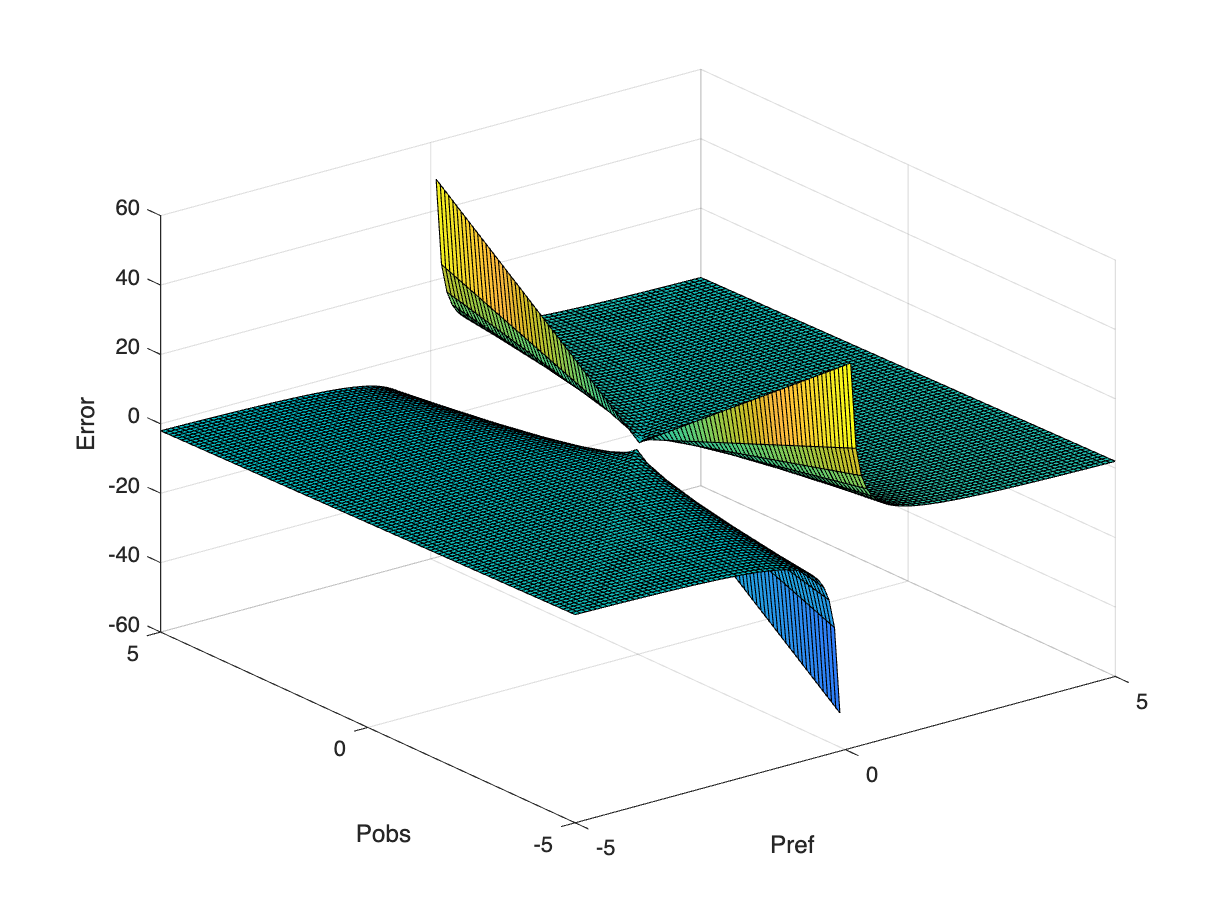

%Error functions testing

%Parameters
%We just need to observe the behavior betwween
%this iteration
x = -5:0.1:5;
y = -5:0.1:5;
fixX = ones(201, 201);
fixX =  fixX *5;
[Pobs, Pref] = ndgrid(x,y);


%First error funtion
%Relative error
for i = 1:length(Pref)
    if Pref(i) == 0
        Pref(i) = 0.005;
    end
    if Pobs(i) == 0
        Pobs(i) = 0.005;
    end
end
err1 = (abs(Pref-Pobs)./(Pref));


figure
surf(Pref, Pobs, err1);
xlabel('Pref'), ylabel('Pobs'), zlabel('Error');

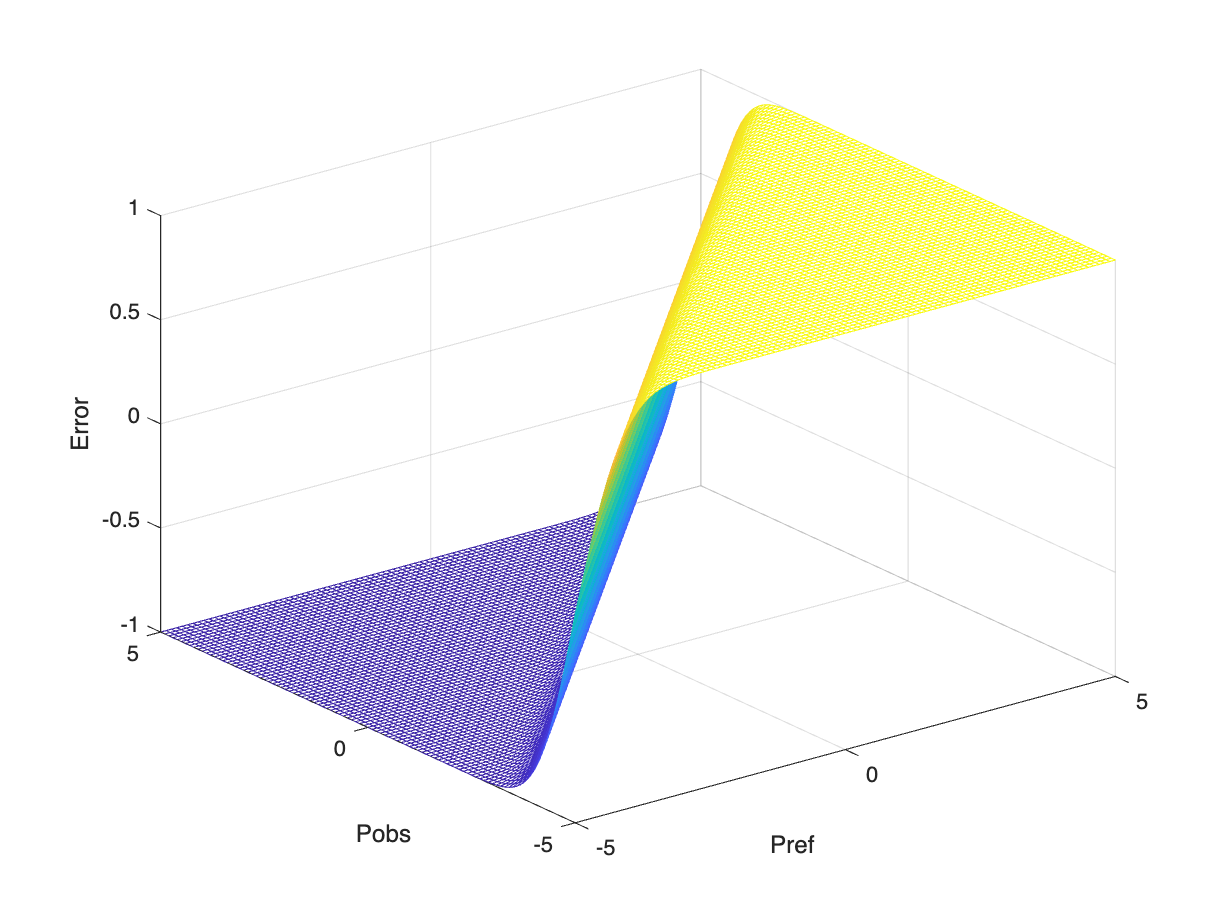


%Error function 2
%the use of erp 

err2 =  erf(Pref-Pobs);
figure
mesh(Pref, Pobs, err2);
xlabel('Pref'), ylabel('Pobs'), zlabel('Error');

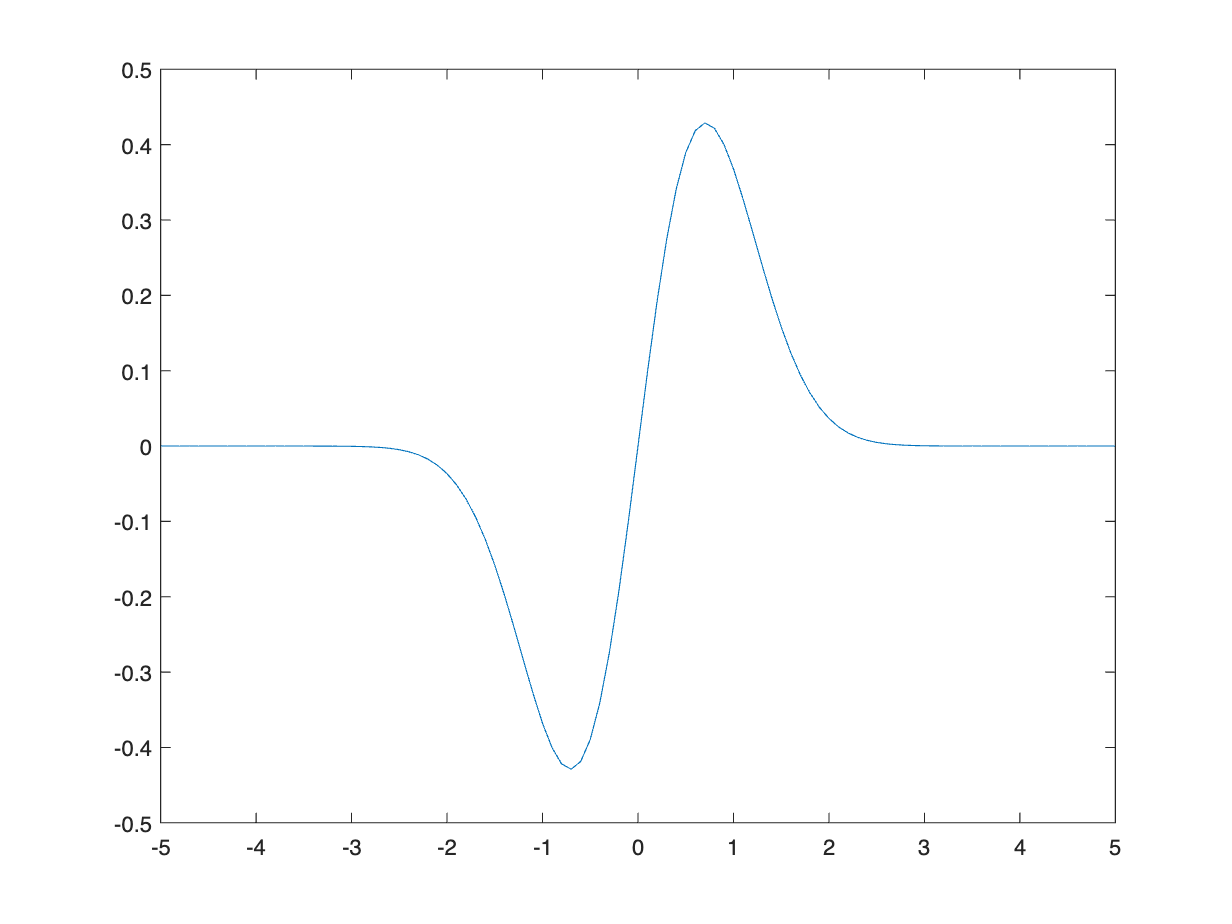

%Error function 3
%The search of a function that satisfices 
% f(error) = - x * exp(-(x-y)(x-y))
% x= pref, y = pobs

%Lineal
err3 = (x) .* exp(-(x.^2));
figure
plot(x, err3);

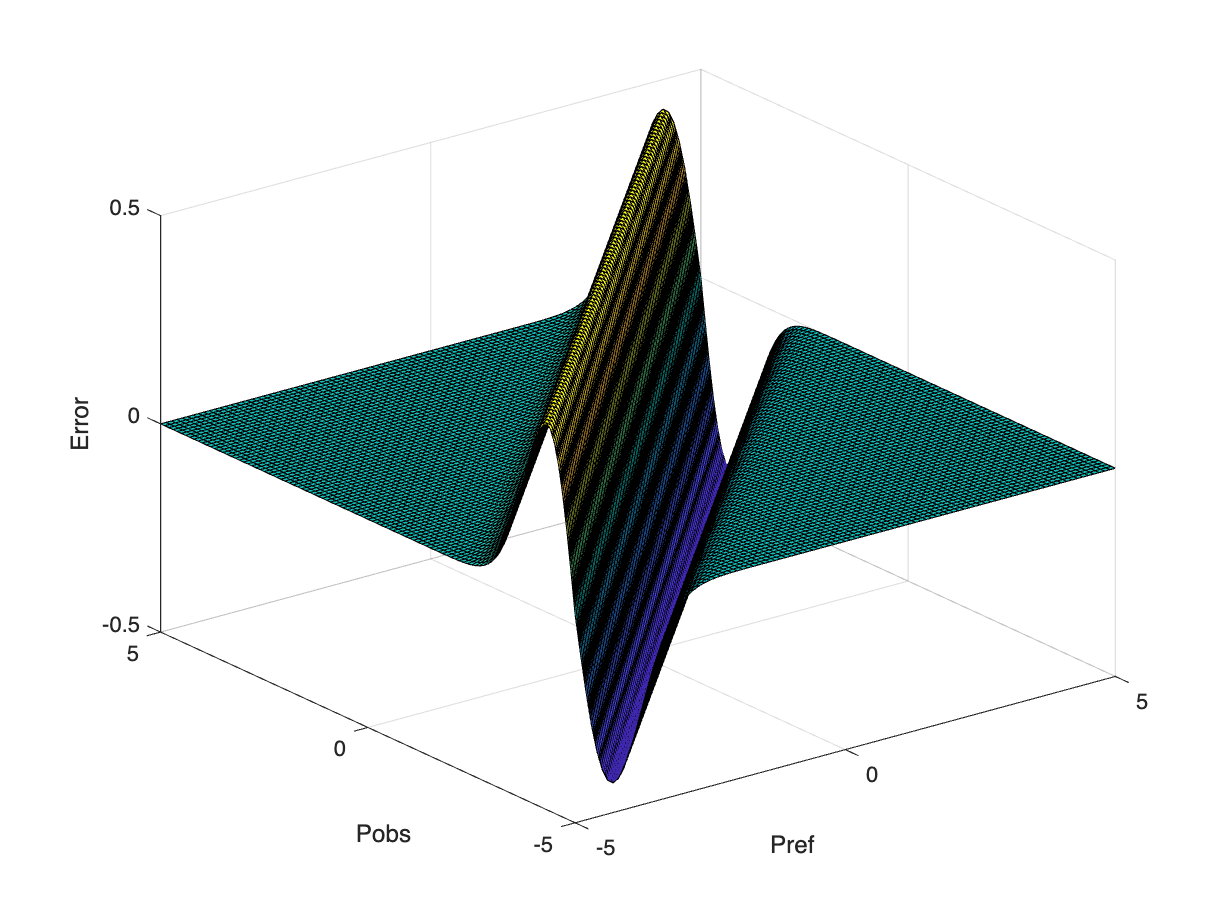


\
figure
surf(Pref, Pobs, err5);
xlabel('Pref'), ylabel('Pobs'), zlabel('Error');

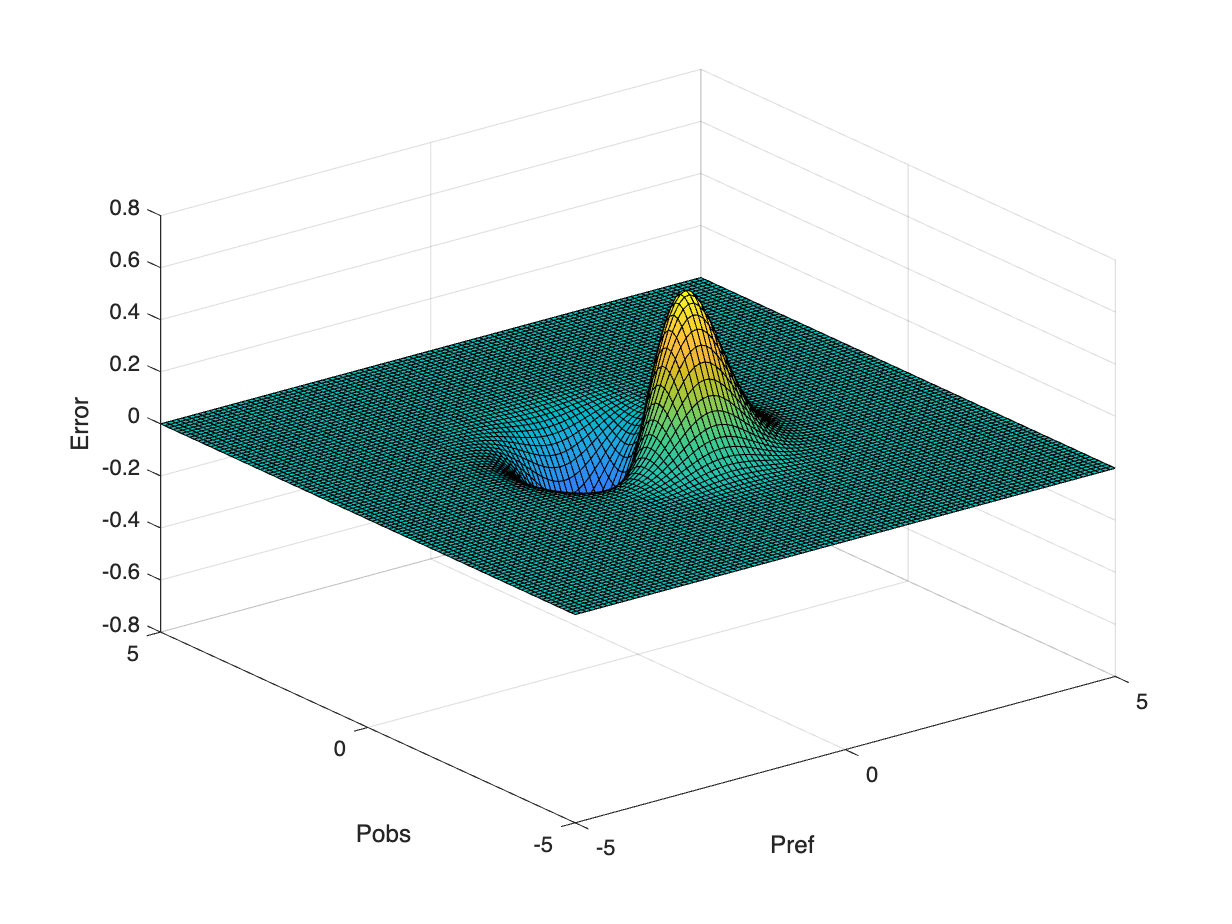

err6 = ((Pref-Pobs) .* exp(-(Pref).^2) .* exp(-(Pobs).^2));
figure
surf(Pref, Pobs, err6);
xlabel('Pref'), ylabel('Pobs'), zlabel('Error');